# Light Curve Fitting

This file is meant to elaborate data obtained by Muniwin to fit a light curve and get results data. 

In this example the light curve of Wasp-48b is obtained from Muniwin data.

## File Importing 

Once you obtain the .txt file containing magnitude and times of the images you can import it here by entering its name:

file = fopen('WASP-48b.txt','r');

The data should be in the following format:* julian day/magnitude/error*

X = fscanf(file,'%f',[3 Inf])';
format longg
jd = X(:,1);%giulian day
Mag = -X(:,2);%magnitude
err = X(:,3);

could be useful to convert the julian day into days

[D,M,Y] = jd2dmy2(jd,false);
%plot(H,Mag)
%errorbar(H,Mag,err);


## Data optimization

Is possible to improve our data into multiple ways to obtain a prettier light curve.

For example we can  divide data into x subarrays of lenght n, after that calculate the average.

%improving of data
%divide my data into x subarrays of length 7, and calculate the average
default = NaN;
%suddivision
n = 10;
MagMat = vec2mat(Mag,n,default)';
DMat = vec2mat(D,n,default)';
% improve, last column cannot be used for the medium
Mmedium = mean(MagMat);
Dmedium = mean(DMat);
%remove the last column with NaN values
Mmedium(:,end) = [];
Dmedium(:,end) = [];

The result will be:

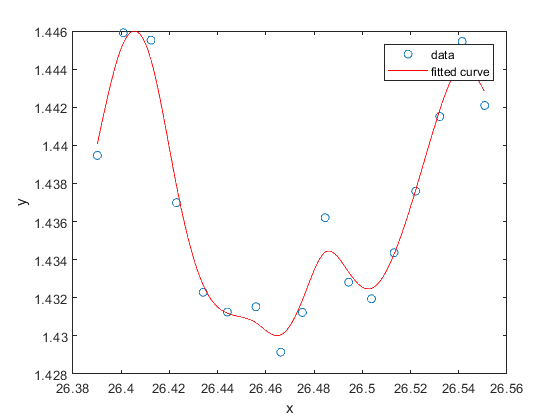

f = fit(Dmedium',Mmedium','smoothingspline');
figure(1)
plot(f,Dmedium,Mmedium,'o');

We can also point out the outlier data so that we can check them and maybe remove:

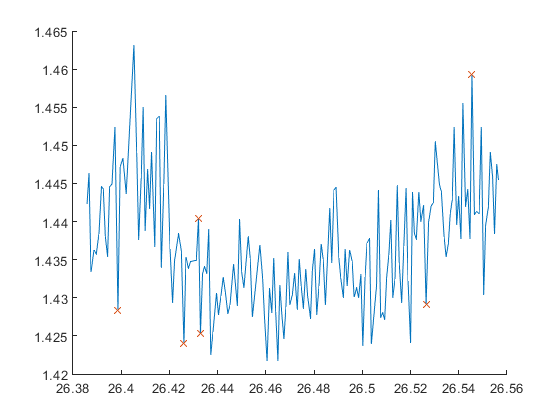

TF = isoutlier(Mag,'movmedian',0.01,'SamplePoints',D);
%Movemedian:Returns true for elements more than three local scaled MAD from the local 
%median over a window length specified by window.
Dout = D;
Mout = Mag;
errout = err;
Dout(TF) = [];
Mout(TF) = [];
errout(TF) = [];
figure(2)
hold on 
plot(D,Mag,D(TF),Mag(TF),'x')
plot(f,Dmedium,Mmedium,'o');%here the outlier are not removed
hold off

## Linear fitting

We want to calculate the transit duration and other parameters. First of all we need to obtain the time for which the transit begins and ends. To do this we use Slmengine.

Slmengine is a very powerful tool that helps you fitting curves in the best way possible. For more information and a list of the possible parameters, you can open the slm_tutorial.html file in *SLMtools/html/slm_tutorial.html *

We want to obtain a 7-segment linear fitting of our data ([exoplanetarchive](https://exoplanetarchive.ipac.caltech.edu/docs/datasethelp/AXA.html)), in such a way that is easy to find the interesting times, we also want to ensure that our curve is always concave up in the relevant part of the transit, those two things are very easy to do with slmengine:

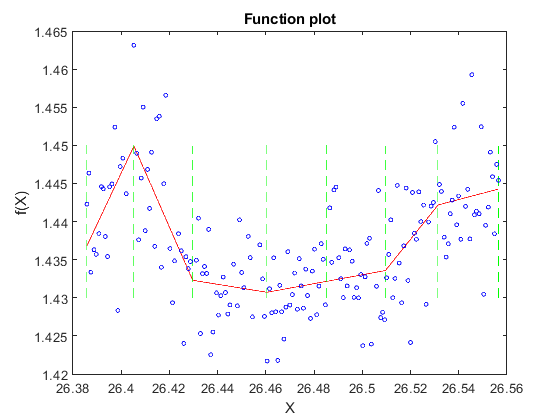

Kn = 8;%to obtain 7 segment we need 8 knots
slmengine(D,Mag,'degree',1,'knots',Kn, 'interiorknots','free','plot','on','ConcaveUp',[26.42 26.52]);

If the curve doesn't look as expected we can do additional manipulation of the data, for example remove uninteresting data such as the one outside the transit.

%delete the unnecessary data after the transit
% Dout(103:end) = [];
% Mout(103:end) = [];
% or making the curve constant after the 7th node
%slmengine(Dout,Mout,'degree',1,'knots',Kn, 'interiorknots','free','plot','on','ConcaveUp',[slm.knots(2)+dist slm.knots(end-1)-dist],'segmentconstant',7);

Those are the results withuot outlier:

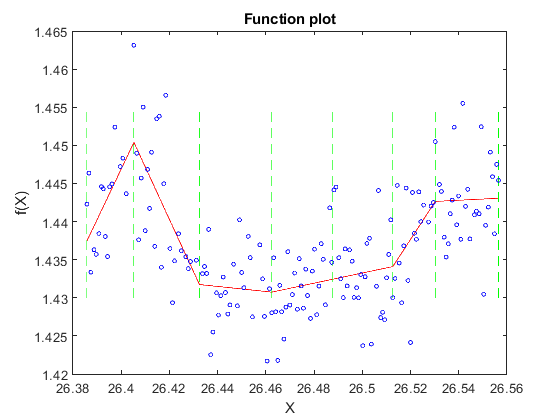

slm1 = slmengine(Dout,Mout,'degree',1,'knots',Kn, 'interiorknots','free','plot','off');
dist = 0.01;
slm = slmengine(Dout,Mout,'degree',1,'knots',Kn, 'interiorknots','free','plot','on','ConcaveUp',[slm1.knots(2)+dist slm1.knots(end-1)-dist]);

The curve should be almost constant before the transit and after it (in this case it isn't before the transit probably because of noisy data).

## Transit times

Once we obtain the wanted curve we can obtain the times as in the figure below:

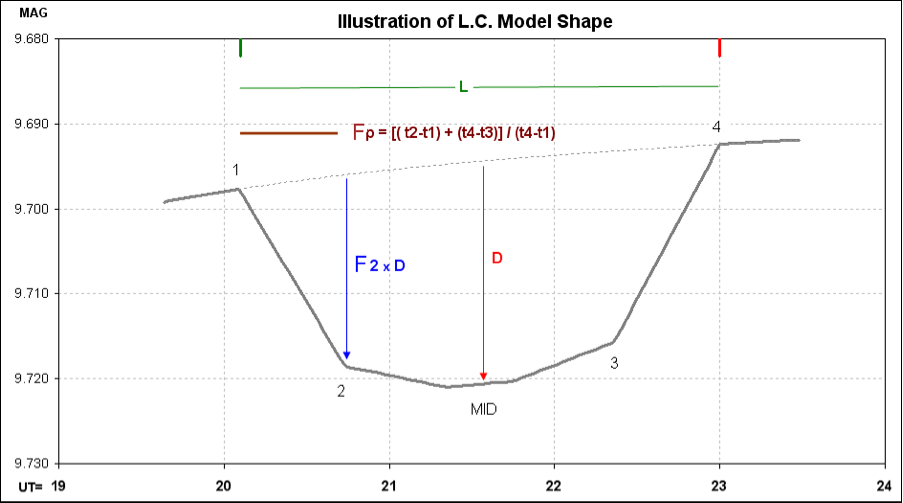

- t1: Beginning of ingress 

- t2: End of ingress 

- t3: Beginning of egress 

- t4: End of egress 

- L: length of transit from t1 to t4

- MD: mid-point of transit

- D: Transit depth at transit midpoint (MD)

- Fp: Partial transit fraction; Fp = [ (t2-t1) + (t4-t3) ] / (t4-t1)

- F2: Fractional transit depth at t2 (with respect to D)

t1 = slm.knots(2);
t2 = slm.knots(3);
t3 = slm.knots(end-2);
t4 = slm.knots(end-1);
tmiddle = (t3+t2)/2;
%Could be useful to compare the following values with the one included in papers.
tt = t4-t1%the total duration,lenght of the transit [days]

tt =          0.124995174942494


tf = t3-t2 %the full duration [days]

tf =         0.0802074990092834


## Transit depth

To obtain the transit depth we should first normalize our data to the normal magnitude of the star.

averageMag = (slmeval(slm.knots(end),slm)+slmeval(slm.knots(end-1),slm))/2

averageMag =           1.44284692003436


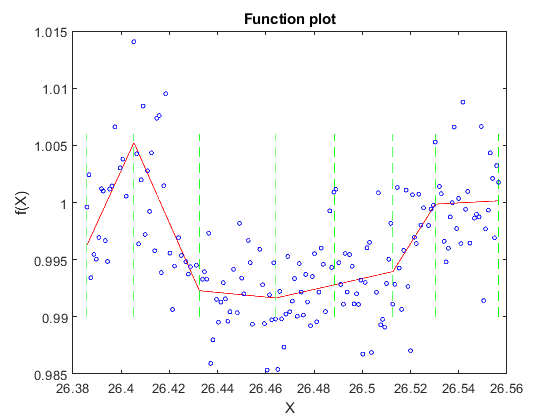

Mnorm = Mout/averageMag;%normalization 
slm2 = slmengine(Dout,Mnorm,'degree',1,'knots',Kn, 'interiorknots','free','plot','on','ConcaveUp',[slm1.knots(2)+dist slm1.knots(end-1)-dist]);

as we can see in this case the minimum magnitude is given by the 4th node:

[MinMag,MinTime] = slmpar(slm2,'minfun')

MinMag =          0.991642558711246


MinTime =           26.4641601217623


Depth = 1-MinMag

Depth =        0.00835744128875415


The depth of the transit is also equal to:


$$\mathrm{Depth}={\left(\frac{R_p }{R_{\mathrm{star}} }\right)}^2$$


Rstar is given and can be found on papers:

Rsun = 695700;%km
Rstar = 1.75*Rsun %km +-0.09

Rstar =      1217475


Rplanet = sqrt(Depth)*Rstar %km

Rplanet =           111300.398482275


This can be compared with papers that for wasp-48b give

Rjup = 7.1492*10^4;%km
RplanetReal = 1.7*Rjup%km+-0.1

RplanetReal =                   121536.4


Considering the noisy data, the one we obtained is an acceptable value.

## Other parameters

One other possible parameter easy to obtain is the impact parameter b, that depends on the variables already found plus the period of the orbit, that can be determined simply by looking how often the transit occurs, this can be found online.

P = 2.14363592; %days orbital period for wasp 48b
%impact parameter pag 120 the exoplanet handbook
b = sqrt(((1-sqrt(Depth))^2-(sin(tf*pi/P)^2)/(sin(tt*pi/P)^2)*(1+sqrt(Depth))^2)/(1-sin(tf*pi/P)^2/sin(tt*pi/P)^2));
%a, semimajor axis
a = Rstar*sqrt(((1+sqrt(Depth))^2-b^2*(1-sin(tt*pi/P)^2))/(sin(tt*pi/P)^2))%km

a =           5360672.31701503


%the real one is
au = 149597870.700;%km astronomical unit
areal = 0.03444*au %real semimajor axis for wasp 48b

areal =             5152150.666908


erra = abs((areal-a)/areal) %error semimajor axis

erra =         0.0404727391701406


we can see that also in this case the result is quite good, and the error is only of 4%.

is also possible to calculate the inclination, knowing that b = a/rstar*cos(i):

incl = rad2deg(acos(Rstar*b/a))

incl =           80.1561765842065


inclReal = 80.09; %° real inclination

It is also possible to find an approximation of the stellar density, as we can see in pag 120 of the exoplanet handbook:

G =  6.674*10^(-11);%m^3kg-1s^-2
Psec = P*24*60*60; %the period must have the SI unit so that we can multiply it times G
rostar = 4*pi^2/(Psec^2*G)*(((1+sqrt(Depth))^2-b^2*(1-sin(tt*pi/P)^2))/(sin(tt*pi/P)^2))^(3/2)%kg/m^3

rostar =           1472.04682311822


%another formula approximation of the last one
rostar2 = 32*Psec/G/pi*Depth^(3/4)*((tt*24*60*60)^2-(tf*24*60*60)^2)^(-3/2)%kg/m^3

rostar2 =           1374.92855165939


Mstar = rostar*4/3*pi*(Rstar*1000)^3 %kg

Mstar =         1.112731518518e+31


Msun = 1.98855*10^30;%kg
Mrealstar = 1.19*Msun %kg

Mrealstar =              2.3663745e+30


errMstar = abs((Mrealstar-Mstar)/Mrealstar)

errMstar =           3.70226297028642


Here the error obtained is much bigger, of the order of the 300%, probably because an accumulation of the errors in calculating the density.

We can also include the formula for the estimation of the planet mass derived from the kepler third law (eq 6.16 pag 120), in this case the result would have non physical meaning because of the high error in the star mass. To get the mass of the planet usually other methods are used, like the Radial Veocity method.

Mplanet = 4*pi^2*(a*1000)^3/Psec^2/G-Mstar

Mplanet =      -8.47086436258568e+30


Mearth = 5.9722*10^24;%kg
Mplanetreal = 311*Mearth %kg 311+-29 for wasp48b

Mplanetreal =              1.8573542e+27


## Theorethical Light Curves

In the following part we try to obtain the theoretical light curve using real data of the star and the eqaution that can be found in "Properties of analytic transit light-curve models - Andr´as P´al "

 doi:10.1111/j.1365-2966.2008.13723.x

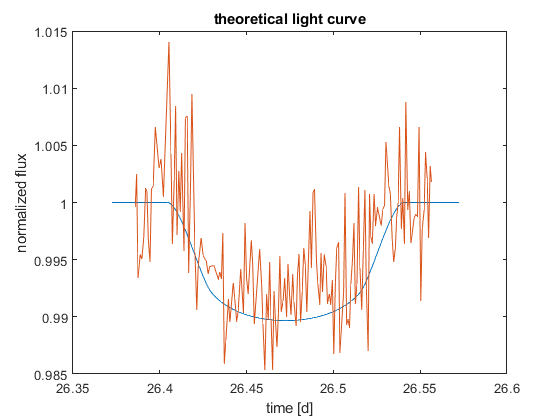

limbcoeff = [0.4 0.4];
tE = tmiddle;%d
TIn = tE-0.1;%d
Tend = 0.1+tE;%d
Periodd = P;
figure(10)
[flux, time] = theoretical_light_curve_Pal(RplanetReal,Rstar,limbcoeff,TIn,Tend,tE,Periodd,areal,inclReal);
plot(time,flux);
hold on 
title('theoretical light curve')
xlabel('time [d]');
ylabel('normalized flux');
plot(Dout,Mnorm)
hold off